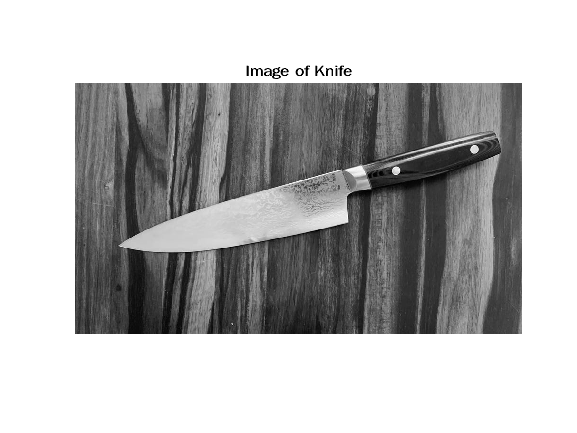

img = imread('knife.jpg');
boxImg = rgb2gray(img);
figure;
imshow(boxImg);
title('Image of Knife');

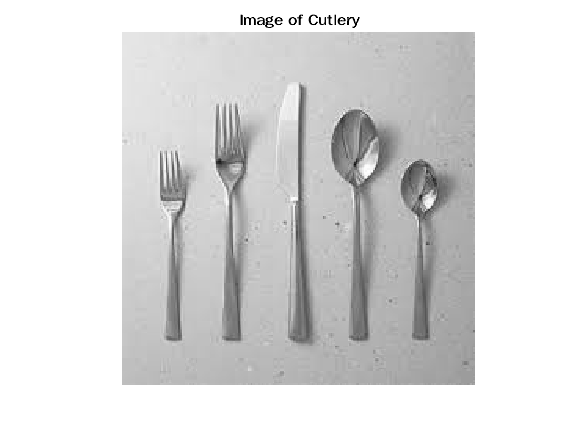

img1 = imread('cutlery.jpeg');
sceneImg = rgb2gray(img1);
figure;
imshow(sceneImg);
title('Image of Cutlery');

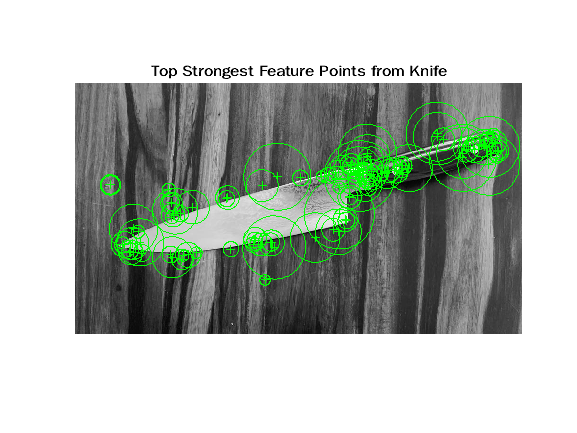

boxImgPoints = detectSURFFeatures(boxImg);

sceneImgPoints = detectSURFFeatures(sceneImg);
figure;
imshow(boxImg);

title('Top Strongest Feature Points from Knife');
hold on;
plot(selectStrongest(boxImgPoints, 100));

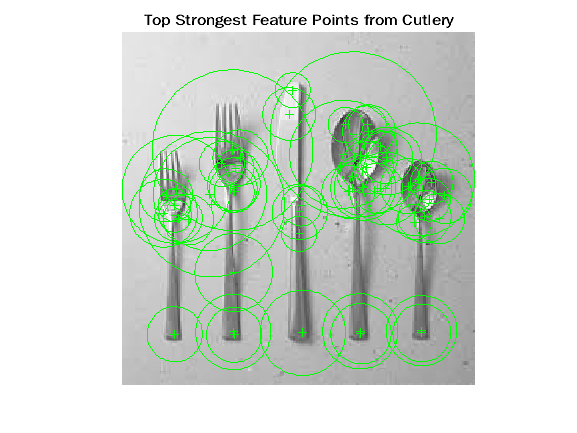

figure;
imshow(sceneImg);

title('Top Strongest Feature Points from Cutlery');
hold on;

plot(selectStrongest(sceneImgPoints, 300));

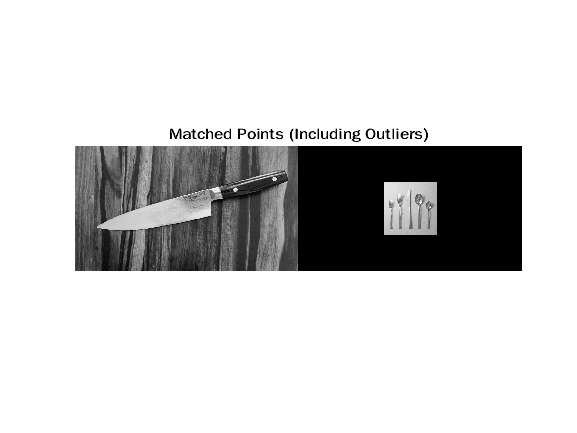

[boxImgFeatures, boxImgPoints] = extractFeatures(boxImg, boxImgPoints);
[sceneImgFeatures, sceneImgPoints] = extractFeatures(sceneImg, sceneImgPoints);
boxImgPairs = matchFeatures(boxImgFeatures, sceneImgFeatures);


matchedBoxImgPoints = boxImgPoints(boxImgPairs(:, 1), :);
matchedSceneImgPoints = sceneImgPoints(boxImgPairs(:, 2), :);
figure;


showMatchedFeatures(boxImg, sceneImg, matchedBoxImgPoints, ...
    matchedSceneImgPoints, 'montage');
title('Matched Points (Including Outliers)');

[tform, inlierIdx] = estimateGeometricTransform2D(matchedBoxImgPoints, matchedSceneImgPoints, 'affine');

Error using vision.internal.geotrans.algEstimateGeometricTransform>checkRuntimeStatus
matchedPoints1 and matchedPoints2 do not have enough points. The number of points in each set must be at least 3.

Error in vision.internal.geotrans.algEstimateGeometricTransform (line 70)
    checkRuntimeStatus(statusCode, status, sampleSize);

Error in 



inlierBoxImgPoints   = matchedBoxImgPoints(inlierIdx, :);
inlierSceneImgPoints = matchedSceneImgPoints(inlierIdx, :);
figure;
showMatchedFeatures(boxImg, sceneImg, inlierBoxImgPoints, ...
    inlierSceneImgPoints, 'montage');
title('Matched Points (Inliers Only)');
boxImgPolygon = [1, 1;...                           
        size(boxImg, 2), 1;...                
        size(boxImg, 2), size(boxImg, 1);... 
        1, size(boxImg, 1);...                 
        1, 1];                   


newBoxImgPolygon = transformPointsForward(tform, boxImgPolygon)
figure;
imshow(sceneImg);
hold on;
line(newBoxImgPolygon(:, 1), newBoxImgPolygon(:, 2), 'Color', 'r');
title('Detected Box');